clear all
clc

load('zzd_pod.mat','zzd')
zzd_pod26 = zzd;
load('t_pod.mat','t')
t_pod26   = t;
load('y_exprm_pod.mat','y_exprm')
% % % y_exprm(:,3) = y_exprm(:,3)*1.15;
% % % save('y_exprm_pod.mat','y_exprm')
y_exprm_pod26 = y_exprm;
t_pod26(2:4) = [];
y_exprm_pod26(2:4,:) = [];

load('zzd.mat','zzd')
load('t.mat','t')
load('y_exprm.mat','y_exprm')

load('zzd_pod6.mat','zzd_pod6')
load('t_pod6.mat','t_pod6')
t_pod6 = [0, t_pod6];
load('y_exprm_pod6.mat','y_exprm_pod6')

y_exprm_ssm   = y_exprm;
zzd_ssm       = [[0;0;zzd(3,1)], zzd];
t_ssm         = [0, t];
t_pod26         = [0, t_pod26];

alpha       = -pi * 0.068;
% alpha       = -pi * 0.02;
R_aft    = [cos(alpha),  sin(alpha), 0;...
            -sin(alpha), cos(alpha), 0;...
            0         , 0,         1];
for i = 1:size(y_exprm_ssm,1)
    y_exprm_ssm(i,:) = (R_aft*y_exprm_ssm(i,:)')';
end

for i = 1:size(y_exprm_pod26,1)
    y_exprm_pod26(i,:) = (R_aft*y_exprm_pod26(i,:)')';
end

for i = 1:size(y_exprm_pod6,1)
    y_exprm_pod6(i,:) = (R_aft*y_exprm_pod6(i,:)')';
end

errs_ssm = y_exprm_ssm - zzd_ssm';  % errs_ssm = errs_ssm./1000;
ISE_ssm  = 0;
for i = 1:size(errs_ssm, 1)
    ISE_ssm = ISE_ssm + sum((errs_ssm(i,:)).^2);
end
ISE_ssm

ISE_ssm = single
663.4595


errs_pod6 = y_exprm_pod6 - zzd_ssm'; % errs_pod6 = errs_pod6./1000;
ISE_pod6  = 0;
for j = 1:size(errs_pod6, 1)
    ISE_pod6 = ISE_pod6 + sum((errs_pod6(j,:)).^2);
end
ISE_pod6

ISE_pod6 = single
2.4012e+04


errs_pod26 = y_exprm_pod26 - zzd_pod26'; % errs_pod26 = errs_pod26./1000;
ISE_pod26  = 0;
for k = 1:size(errs_pod26, 1)
    ISE_pod26 = ISE_pod26 + sum((errs_pod26(k,:)).^2);
end
ISE_pod26

ISE_pod26 = single
1.4685e+03


rel_ISE_ssm   = 0;
rel_ISE_pod6  = (ISE_pod6 - ISE_ssm)/ISE_ssm  .* 100

rel_ISE_pod6 = single
3.5191e+03

rel_ISE_pod26 = (ISE_pod26 - ISE_ssm)/ISE_ssm .* 100

rel_ISE_pod26 = single
121.3471

rel_ISEs  = [rel_ISE_ssm, round(rel_ISE_pod6), round(rel_ISE_pod26)];

% figure; clf; hold on;
% plot_setting
% subplot(2,2,1); hold on;
% h1=plot(t_ssm,zzd_ssm(1,:),'k-',LineWidth=4,DisplayName='Target')
% h2=plot(t_ssm,y_exprm_ssm(:,1),'b--',LineWidth=4,DisplayName='SSM-MPC')
% h3=plot(t_pod6,y_exprm_pod6(:,1),'g-.',LineWidth=4,DisplayName='POD(6D)-MPC')
% h4=plot(t_pod26,y_exprm_pod26(:,1),'m:',LineWidth=4,DisplayName='POD(26D)-MPC')
% xlim([t(1)-0.001,t(end)])
% grid on
% xlabel('$t$/(s)',Interpreter='latex',FontSize=16)
% ylabel('$X$/(mm)',Interpreter='latex',FontSize=16)
% % legend('show',Interpreter='latex',fontsize=20)
% box on
% % plot_setting
% 
% subplot(2,2,2); hold on;
% plot(t_ssm,zzd_ssm(2,:),'k-',LineWidth=4,DisplayName='Target')
% plot(t_ssm,y_exprm_ssm(:,2),'b--',LineWidth=4,DisplayName='SSM-MPC')
% plot(t_pod6,y_exprm_pod6(:,2),'g-.',LineWidth=4,DisplayName='POD(6D)-MPC')
% plot(t_pod26,y_exprm_pod26(:,2),'m:',LineWidth=4,DisplayName='POD(26D)-MPC')
% xlim([t(1)-0.001,t(end)])
% grid on
% xlabel('$t$/(s)',Interpreter='latex',FontSize=16)
% ylabel('$Y$/(mm)',Interpreter='latex',FontSize=16)
% % legend('show',Interpreter='latex',fontsize=20)
% box on
% % plot_setting
% 
% subplot(2,2,3); hold on;
% plot(t_ssm,zzd_ssm(3,:),'k-',LineWidth=4,DisplayName='Target')
% plot(t_ssm,y_exprm_ssm(:,3),'b--',LineWidth=4,DisplayName='SSM-MPC')
% plot(t_pod6,y_exprm_pod6(:,3),'g-.',LineWidth=4,DisplayName='POD(6D)-MPC')
% plot(t_pod26,y_exprm_pod26(:,3),'m:',LineWidth=4,DisplayName='POD(26D)-MPC')
% xlim([t(1)-0.1,t(end)])
% grid on
% xlabel('$t$/(s)',Interpreter='latex',FontSize=16)
% ylabel('$Z$/(mm)',Interpreter='latex',FontSize=16)
% % legend('show',Interpreter='latex',fontsize=20)
% box on
% % plot_setting
% 
% subplot(2,2,4); hold on;
% % x_labels = {['SSM','\\\\','(6D)'], ['POD','\\\\','(6D)'], ['POD','\\\\','(26D)']};  % x轴标签
% x_labels = {'SSM(6D)', 'POD(6D)', 'POD(26D)'};  % x轴标签
% box on
% % ylim([0, 260])
% ylabel('Relative ISE ($\%$)',Interpreter='latex',FontSize=12)
% h = bar(x_labels, rel_ISEs);
% h.FaceColor = 'flat';
% h.EdgeColor = 'none';
% h.CData = [
%     0 0 1;   % 第1个柱子颜色（蓝）
%     0 1 0;   % 第2个柱子颜色（红）
%     1 0 1];  % 第3个柱子颜色（绿）
% ax = gca;  % 获取当前坐标轴句柄
% ax.TickLabelInterpreter = 'latex';
% ax.FontSize = 12;
% 
% x_pos = h.XData;  % 柱子的x坐标（自动生成，与标签对应）
% y_height = h.YData;  % 柱子的高度（即rel_ISEs的值）
% 
% 
% % 在柱子中心上方添加文本
% text(x_pos(1), ...       % x坐标（柱子位置）
%      y_height(1), ...    % y坐标（柱子高度，文本将放在此高度上方）
%      '$\textbf{Baseline}$', ...       % 文本内容
%      'HorizontalAlignment', 'center', ...  % 水平居中
%      'VerticalAlignment', 'bottom', ...     % 垂直对齐在柱子顶部
%      'FontSize', 12, ...                    % 字体大小
%      'Color', 'black',...
%      'Interpreter', 'latex');                     % 文本颜色
% text(x_pos(2), ...       % x坐标（柱子位置）
%      y_height(2), ...    % y坐标（柱子高度，文本将放在此高度上方）
%      '$\textbf{3519\%}$', ... %[num2str(rel_ISEs(2)), '$\%$'], ...       % 文本内容
%      'HorizontalAlignment', 'center', ...  % 水平居中
%      'VerticalAlignment', 'bottom', ...     % 垂直对齐在柱子顶部
%      'FontSize', 12, ...                    % 字体大小
%      'Color', 'black',...
%      'Interpreter', 'latex');                     % 文本颜色
% text(x_pos(3), ...       % x坐标（柱子位置）
%      y_height(3), ...    % y坐标（柱子高度，文本将放在此高度上方）
%      '$\textbf{121\%}$', ... %[num2str(rel_ISEs(3)), '$\%$'], ...       % 文本内容
%      'HorizontalAlignment', 'center', ...  % 水平居中
%      'VerticalAlignment', 'bottom', ...     % 垂直对齐在柱子顶部
%      'FontSize', 12, ...                    % 字体大小
%      'Color', 'black',...
%      'Interpreter', 'latex');                     % 文本颜色
% 
% 
% legend_handles = [h1; h2; h3; h4];
% legend_labels = {'Target'; 'SSM(6D)'; 'POD(6D)'; 'POD(26D)'};
% 
% % 创建底部图例
% hLegend = legend(legend_handles, legend_labels, ...
%        'Location', 'west', ...  % 底部外侧
%        'Orientation', 'horizontal', ...  % 水平排列 horizontal
%        'NumColumns', 4, ...'NumColumns', 4, ...              % 5 列显示
%        'FontSize', 12,...
%        'Interpreter', 'latex',...
%        'IconColumnWidth', 60);                  % 字体大小

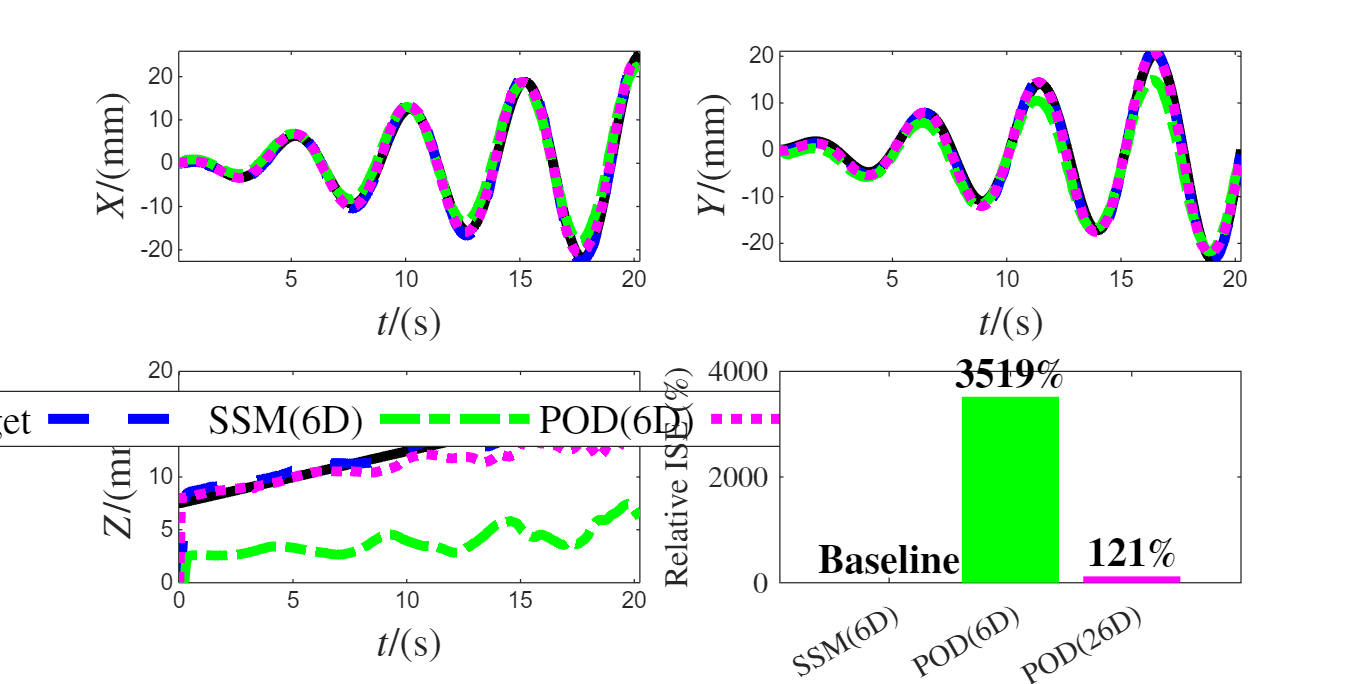

figure; clf;
plot_setting
% 创建2×2的网格布局
% tlo = tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
tlo = tiledlayout(2, 2, 'TileSpacing', 'compact');
% 第一个子图 (X方向)
nexttile; hold on;
plot(t_ssm, zzd_ssm(1,:), 'k-', 'LineWidth', 4, 'DisplayName', 'Target');
plot(t_ssm, y_exprm_ssm(:,1), 'b--', 'LineWidth', 4, 'DisplayName', 'SSM-MPC');
plot(t_pod6, y_exprm_pod6(:,1), 'g-.', 'LineWidth', 4, 'DisplayName', 'POD(6D)-MPC');
plot(t_pod26, y_exprm_pod26(:,1), 'm:', 'LineWidth', 4, 'DisplayName', 'POD(26D)-MPC');
xlim([t(1)-0.001, t(end)]);

xlabel('$t$/(s)', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('$X$/(mm)', 'Interpreter', 'latex', 'FontSize', 16);
box on;

% 第二个子图 (Y方向)
nexttile; hold on;
plot(t_ssm, zzd_ssm(2,:), 'k-', 'LineWidth', 4, 'DisplayName', 'Target');
plot(t_ssm, y_exprm_ssm(:,2), 'b--', 'LineWidth', 4, 'DisplayName', 'SSM-MPC');
plot(t_pod6, y_exprm_pod6(:,2), 'g-.', 'LineWidth', 4, 'DisplayName', 'POD(6D)-MPC');
plot(t_pod26, y_exprm_pod26(:,2), 'm:', 'LineWidth', 4, 'DisplayName', 'POD(26D)-MPC');
xlim([t(1)-0.001, t(end)]);

xlabel('$t$/(s)', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('$Y$/(mm)', 'Interpreter', 'latex', 'FontSize', 16);
box on;

% 第三个子图 (Z方向)
nexttile; hold on;
h1 = plot(t_ssm, zzd_ssm(3,:), 'k-', 'LineWidth', 4, 'DisplayName', 'Target');
h2 = plot(t_ssm, y_exprm_ssm(:,3), 'b--', 'LineWidth', 4, 'DisplayName', 'SSM-MPC');
h3 = plot(t_pod6, y_exprm_pod6(:,3), 'g-.', 'LineWidth', 4, 'DisplayName', 'POD(6D)-MPC');
h4 = plot(t_pod26, y_exprm_pod26(:,3), 'm:', 'LineWidth', 4, 'DisplayName', 'POD(26D)-MPC');
xlim([t(1)-0.1, t(end)]);

xlabel('$t$/(s)', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('$Z$/(mm)', 'Interpreter', 'latex', 'FontSize', 16);
box on;

% 第四个子图 (柱状图)
nexttile; hold on;
x_labels = {'SSM(6D)', 'POD(6D)', 'POD(26D)'};
box on;
ylabel('Relative ISE ($\%$)', 'Interpreter', 'latex', 'FontSize', 16);
h = bar(x_labels, rel_ISEs);
h.FaceColor = 'flat';
h.EdgeColor = 'none';
h.CData = [
    0 0 1;   % 蓝色
    0 1 0;   % 绿色
    1 0 1];  % 品红
ax = gca;
ax.TickLabelInterpreter = 'latex';
ax.FontSize = 12;

% 在柱子上方添加文本
x_pos = h.XData;
y_height = h.YData;
text(x_pos(1), y_height(1), '$\textbf{Baseline}$', ...
     'HorizontalAlignment', 'center', ...
     'VerticalAlignment', 'bottom', ...
     'FontSize', 16, ...
     'Color', 'black', ...
     'Interpreter', 'latex');
text(x_pos(2), y_height(2), '$\textbf{3519\%}$', ...
     'HorizontalAlignment', 'center', ...
     'VerticalAlignment', 'bottom', ...
     'FontSize', 16, ...
     'Color', 'black', ...
     'Interpreter', 'latex');
text(x_pos(3), y_height(3), '$\textbf{121\%}$', ...
     'HorizontalAlignment', 'center', ...
     'VerticalAlignment', 'bottom', ...
     'FontSize', 16, ...
     'Color', 'black', ...
     'Interpreter', 'latex');

% 创建底部图例
legend_handles = [h1; h2; h3; h4];
legend_labels = {'Target'; 'SSM(6D)'; 'POD(6D)'; 'POD(26D)'};

hLegend = legend(legend_handles, legend_labels, ...
       'Location', 'north', ...  % 底部外侧
       'Orientation', 'horizontal', ...
       'NumColumns', 4, ...
       'FontSize', 16, ...
       'Interpreter', 'latex', ...
       'IconColumnWidth', 60);

% 
% % 调整布局
% tightfig;